# Ray Tracing PCR Model

v = 100; % volume added to PCR tube
[r, dz, height] = pcr_tube_to_washers(80, v); %function dividing this volume into 80 equivalent washers
volume_of_washers(r,dz) % function summing up the incremental washer volumes

ans = 93.0756

volume_difference = v - volume_of_washers(r,dz) % difference between input volume and the volume of washers

volume_difference = 6.9244

height % height which the volume reaches wrt z=0

height = 9.6322

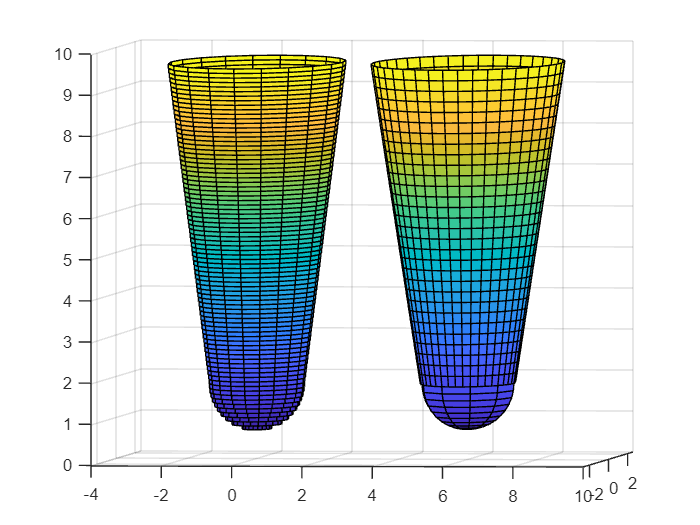

clf
[x_s1,y_s1,z_s1] = ellipsoid1(1.3080,1.3080,1.120,[0 2*pi],[pi/2 pi],6,0,0.721+1.120);
% bottom portion of pcr tube in the form of an ellipsoid, with the given
% parameters (see function)
surf(x_s1, y_s1, z_s1)
hold on

[x_co1,y_co1,z_co1] = vertical_cone(1.3080,2.6645,height-1.841,6,0,1.841);
% vertical conical portion of pcr tube with given parameters (measured on
% ImageJ from the diagrams)
surf(x_co1, y_co1, z_co1)
hold on

for i=1:length(r)
    % for loop creating the incremental washers for each radius with
    % individual heights of dz

    top = height - dz*(i-1);
    bottom = height - dz*i;
    z1 = linspace(bottom,top,2);
    rad = r(i);
    theta = (0:0.05:1)*(2*pi);


    [THETA, Z] = meshgrid(theta,z1);
    x = rad.*cos(THETA);
    y = rad.*sin(THETA);
    z = Z;

    surf(x,y,z)
    hold on
end
hold off
% results compare the pcr tube (on right) with the washer created pcr tube

view([5.90 2.11])

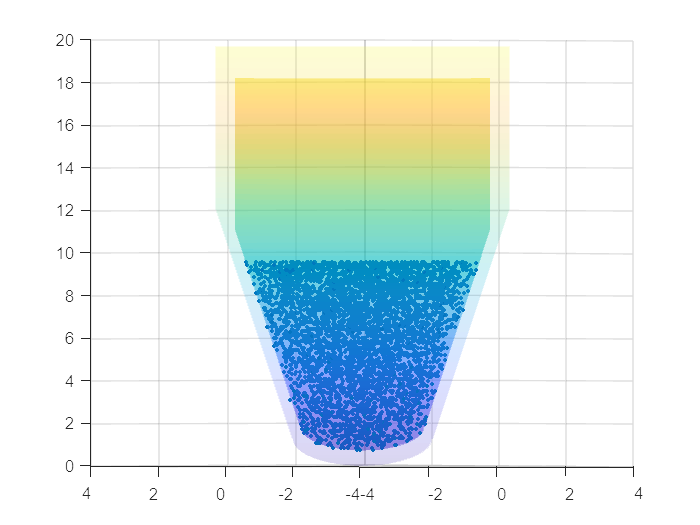

clf
[x_s,y_s,z_s] = ellipsoid1(1.4695,1.4695,1.270,[0 2*pi],[pi/2 pi],0,0,1.270);
surf(x_s, y_s, z_s, 'FaceAlpha',0.1, 'EdgeColor','none')
hold on

[x_co,y_co,z_co] = vertical_cone(1.4695,3.068,10.787,0,0,1.270);
surf(x_co, y_co, z_co, 'FaceAlpha',0.1, 'EdgeColor','none')
hold on

[x_s2,y_s2,z_s2] = ellipsoid1(1.3080,1.3080,1.120,[0 2*pi],[pi/2 pi],0,0,0.721+1.120);
surf(x_s2, y_s2, z_s2, 'FaceAlpha',0.3, 'EdgeColor','none')
hold on

[x_co2,y_co2,z_co2] = vertical_cone(1.3080,2.6645,9.258,0,0,0.721+1.120);
surf(x_co2, y_co2, z_co2, 'FaceAlpha',0.3, 'EdgeColor','none')

[cy1_x,cy1_y,cy1_z] = vertical_cylinder(3.068,7.638,0,0,1.270+10.787);
[cy2_x,cy2_y,cy2_z] = vertical_cylinder(2.6645,7.105,0,0,0.721+1.120+9.258);

surf(cy1_x,cy1_y,cy1_z,'FaceAlpha',0.1,'EdgeColor','none')
hold on
surf(cy2_x,cy2_y,cy2_z,'FaceAlpha',0.3,'EdgeColor','none')

% similar as previous section, though this part defines the interior volume
% (water) and the exterior polypropylene casing for the pcr tube itself



points = generate_washer_points(r,dz,height,5000);
% function generating points in each incremental washer, based on their
% respective volumes
plot3(points(:,1),points(:,2),points(:,3),'.')


view([-44.45 0.19])

This section visualizes the ray tracing process of the individual vectors traced from a small amount of ranndomly generated points within the selected volume. The real numerical simulation will use many more points, though the visualization is not as clear with a large amount of points.

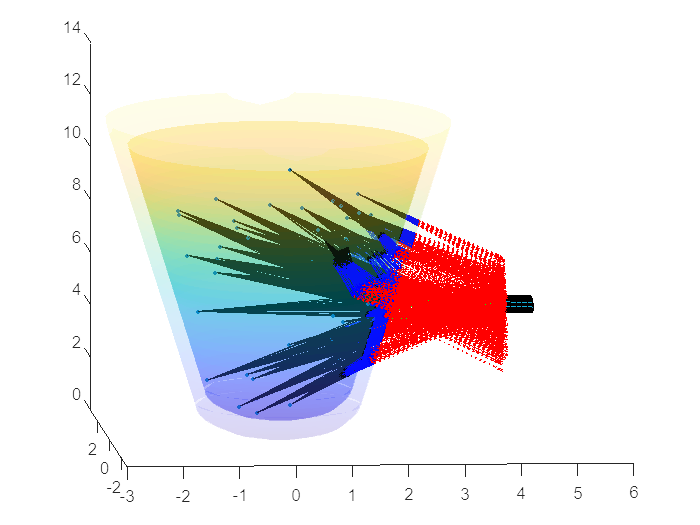

clf
mid = [4 0 5];
acceptance_angle = 0.2218;
radius = 0.3;

% [x_cone, y_cone, z_cone] = cone_acceptance_angle(acceptance_angle,mid);
% surf(x_cone, y_cone, z_cone)


hold on
[x_s,y_s,z_s] = ellipsoid1(1.4695,1.4695,1.270,[0 2*pi],[pi/2 pi],0,0,1.270);
surf(x_s, y_s, z_s, 'FaceAlpha',0.1, 'EdgeColor','none')
hold on

[x_co,y_co,z_co] = vertical_cone(1.4695,3.068,10.787,0,0,1.270);
surf(x_co, y_co, z_co, 'FaceAlpha',0.1, 'EdgeColor','none')
hold on

[x_s2,y_s2,z_s2] = ellipsoid1(1.3080,1.3080,1.120,[0 2*pi],[pi/2 pi],0,0,0.721+1.120);
surf(x_s2, y_s2, z_s2, 'FaceAlpha',0.3, 'EdgeColor','none')
hold on

[x_co2,y_co2,z_co2] = vertical_cone(1.3080,2.6645,9.258,0,0,0.721+1.120);
surf(x_co2, y_co2, z_co2, 'FaceAlpha',0.3, 'EdgeColor','none')

[x_o,y_o,z_o] = optical_fiber_head(mid, radius);
% visual representation of the optical fiber
surf(x_o, y_o, z_o)
hold on

points = generate_washer_points(r,dz,height,40);
plot3(points(:,1),points(:,2),points(:,3),'.')
hold on

view([-4.08 8.74])
    
for i=1:length(points)
    % for each point, the vector plot function is called, and then quiver3
    % is used to plot the initial rays, refracted rays across the tube, and
    % the rays reaching the detector which are accepted and not accepted

    [initial, initial2, accepted, not_accepted] = vector_plot(points(i,:),40,mid,radius,acceptance_angle);

    quiver3(initial(:,1),initial(:,2),initial(:,3),initial(:,4),initial(:,5),initial(:,6),0,'k')
    quiver3(initial2(:,1),initial2(:,2),initial2(:,3),initial2(:,4),initial2(:,5),initial2(:,6),0,'b')

    quiver3(accepted(:,1),accepted(:,2),accepted(:,3),accepted(:,4),accepted(:,5),accepted(:,6),0,'g',LineWidth=1)
    quiver3(not_accepted(:,1),not_accepted(:,2),not_accepted(:,3),not_accepted(:,4),not_accepted(:,5),not_accepted(:,6),0,'r',LineStyle=':')
    hold on
    warning('off')
end
hold off
ylim([-3 3])
xlim([-3 mid(1)+2])

Building on the previous section, this section performs the same ray tracing process though without directly showing the vectors. Instead, it takes the final results, and colours the points that have accepted rays in green, and those without in red. This is shown in comparison with the optical fiber acceptance angle, which is modeled as a cone, to see the impact of the refraction across the multiple mediums in the pcr tube.

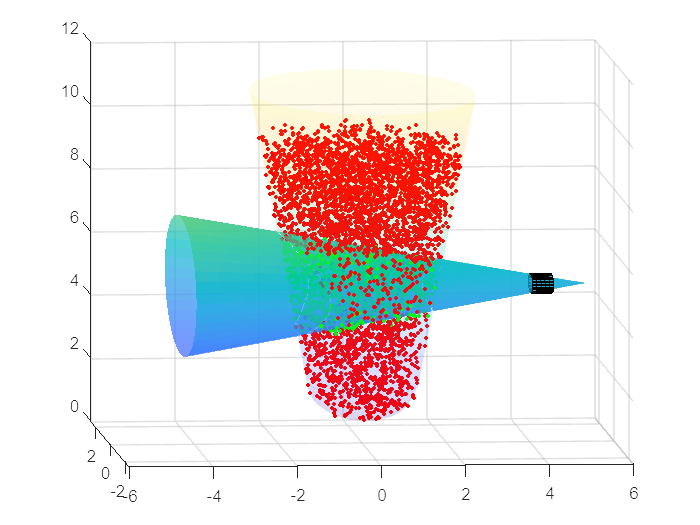

clf
mid = [4 0 5];

acceptance_angle = 0.2218;
radius = 0.3;

[x_cone, y_cone, z_cone] = cone_acceptance_angle(acceptance_angle,mid,radius);
surf(x_cone, y_cone, z_cone,'FaceAlpha',0.7, 'EdgeColor','none')

hold on

% [x_s,y_s,z_s] = ellipsoid1(1.4695,1.4695,1.270,[0 2*pi],[pi/2 pi],0,0,1.270);
% surf(x_s, y_s, z_s, 'FaceAlpha',0.1, 'EdgeColor','none')
% hold on
% 
% [x_co,y_co,z_co] = vertical_cone(1.4695,3.068,10.787,0,0,1.270);
% surf(x_co, y_co, z_co, 'FaceAlpha',0.1, 'EdgeColor','none')
% hold on

[x_s2,y_s2,z_s2] = ellipsoid1(1.3080,1.3080,1.120,[0 2*pi],[pi/2 pi],0,0,0.721+1.120);
surf(x_s2, y_s2, z_s2, 'FaceAlpha',0.1, 'EdgeColor','none')
hold on

[x_co2,y_co2,z_co2] = vertical_cone(1.3080,2.6645,9.258,0,0,0.721+1.120);
surf(x_co2, y_co2, z_co2, 'FaceAlpha',0.1, 'EdgeColor','none')

[x_o,y_o,z_o] = optical_fiber_head(mid, radius);
% visual representation of the optical fiber
surf(x_o, y_o, z_o)
hold on


points = generate_washer_points(r,dz,height,5000);

% checking to see how much refraction plays a role on the initial
% acceptance angle cone for computation efficiency

a_points = zeros(length(points),3);
na_points = zeros(length(points),3);

counter_a = 1;
counter_na = 1;

% view([-4.08 8.74])

for i=1:length(points)
    warning('off')

    [initial, initial_2, accepted, not_accepted] = vector_plot(points(i,:),100,mid,radius,acceptance_angle);
    if isempty(accepted)
        na_points(counter_na,:) = points(i,:);
        counter_na = counter_na + 1;
    else
        a_points(counter_a,:) = points(i,:);
        counter_a = counter_a + 1;
    end
end


a_points = a_points(1:counter_a-1,:);
na_points = na_points(1:counter_na-1,:);

plot3(a_points(:,1),a_points(:,2),a_points(:,3),'.','Color','g')
hold on
plot3(na_points(:,1),na_points(:,2),na_points(:,3),'.','Color','r')

mid = [4 0 5];
acceptance_angle = 0.2218;
radius = 0.3;

lambda_ex = [495 535 650]; 
lambda_em = [516 556 670];

medians = [486 527 524 570 636 679];
median_intensities = [0.8552 0.8701 0.7932 0.7579 0.8666 0.8887];

% These arethe alpha and beta terms (alpha in row 1, and beta in row 2) for
% the log normal functions fit to the experimentatall excitation and
% emission spectra of the FAM, HEX, and Cy5 fluorophores respectively. 


Ex_co = [0.04229 0.04558 0.02026; 0.5072 0.4951 0.5773];
Em_co = [0.03523 0.06098 0.02957; 0.4814 0.3768 0.5644];

last_real_Ex = [219 257 400]; Ex_max = [518.646 556.939 699.358];
first_real_Em = [189 241 338]; Em_min = [487.615 539.601 636.182];

fun1 = ex_spectrum(Ex_co(1,1),Ex_co(2,1),lambda_ex(1));
fun2 = em_spectrum(Em_co(1,1),Em_co(2,1),lambda_em(1));

fun3 = ex_spectrum(Ex_co(1,2),Ex_co(2,2),lambda_ex(2));
fun4 = em_spectrum(Em_co(1,2),Em_co(2,2),lambda_em(2));

fun5 = ex_spectrum(Ex_co(1,3),Ex_co(2,3),lambda_ex(3));
fun6 = em_spectrum(Em_co(1,3),Em_co(2,3),lambda_em(3));

range = [340 780];
pixels = 256;

%find_total_power(total_points, num_vectors, volume, mid, radius, acceptance_angle, excitation_power, excita.quantum_yield, c, extinction_coeff)
power_factors = zeros(pixels, 1);


The microspectrometer which we wish to use, the Hamamatsu C11009MA has 256 pixels with a range from 340-780 nm. This section divides the spectrometer into 256 separate power readings at each pixel. Currently it is using only the FAM excitation and emission spectra, which were modeled on a separate file, though it could be adjusted to account for multiple fluorophores. The normalized excitation and emission spectra are used, so the final value is simply a ratio considering the original excitation light exciting the solution to be 1. This can be used to calculate individual pixel ratios, or the total, while adjusting the acceptance angle, and position of the optical fiber. 

tic
for i=1:256
    x = 340+1.7188*(i-1); % wavelength value
    if x>=Em_min(1) && x<=Ex_max(1)
        %  if this wavelength is within the bounds of the excitation and
        %  emission spectra
        power_factors(i) = find_total_power(1000, 100, 100, mid,radius,acceptance_angle,fun2(x),0.9,1,83000*(fun1(x)));
    else
        if x<=Ex_max(1)
            % if pixel value is below the max excitation but not above the
            % minimum emission, then no light within that wavelength will
            % be emitted
            power_factors(i) = 0;
        else 
            if x>=Em_min(1)
                %if pixel value is greater than the minimum emission but
                %above the maximum excitation value, then no power will be
                %lost across the solution for the ray accepted by the
                %optical fiber
                power_factors(i) = find_total_power(1000, 200, 100,mid,radius,acceptance_angle,fun2(x),0.9,1,0);
            end
        end
    end
end
final_ratio = sum(power_factors)

final_ratio = 9.7500e-06

toc

Elapsed time is 363.770669 seconds.


#### Ray Tracing Functions

function ratio_total_power = find_total_power(total_points, num_vectors, volume, mid, radius, acceptance_angle, excitation_power, quantum_yield, c, extinction_coeff)
% if we aren't using excitation light and the emission and absorption
% spectra as functions, we can either use the absorption value at the peak
% excitation light, or the excitation light intensity at the median
% absorption coefficient
rho1 = 0.1455; % rho value for inner cone of pcr tube
rho2 = 0.1471; % rho value outer cone of pcr tube
p1 = [1.3080 1.8410]; %  radius and z value of inner cone at its bottom
p2 = [1.4695 1.270]; %  radius and z value of outer cone at its bottom


h = (radius*2)*1.5; w = h;
num_washers = round(total_points/60); % average of 70 points per washer, making less  input values
[r,dz,height] = pcr_tube_to_washers(num_washers,volume);
points = generate_washer_points(r,dz,height,total_points);
power_factors = zeros(num_washers,1);
excitation_powers = excitation_power_array2(r, dz/10, extinction_coeff, c, excitation_power);
% converting units to centimeters instead of mm, and mol/L
num_points = point_distribution(r,dz,total_points);


rho = acceptance_angle*1.3; % expanding the range of the acceptance angle to account for refraction, this can be made larger or smaller 
x_start = (radius/tan(rho)) + mid(1); % x coordinates of the start of the acceptance angle cone of the optical fiber


counter = 1;
for i=1:num_washers % incrementing the points at each washer level 
    power_factors_washer = zeros(num_points(i),1); % power factors for the specific level
    for j=1:num_points(i) % incrementing each point in the specific washer level
        x = -(points(counter,1)-x_start);
        dist = x*tan(rho); % radius value along the y-z plane of the acceptance angle cone at the specific x value
        if distance_2d(mid(2),points(counter,2),mid(3),points(counter,3)) <= dist % if the point's distance from the mid y and z value are within the radius range, then we proceed, if not they
            % are likely not to be accepted by the optical fiber and can be
            % ommited 

            initial_vectors = generate_vectors(h,w,mid,points(counter,:),num_vectors);
            % vectors intersection with the first cone (aka the water to
            % polypropylene)
            initial_startpoints = (ones(num_vectors,3)).*points(counter,:);

            [initial_endpoints, normal_vectors] = vect_cone_intersection(initial_startpoints,initial_vectors,rho1,p1);
            refracted_1 = refracted_vectors(initial_vectors, normal_vectors, 1.333, 1.49); 
            % vectors intersection with second cone (the polypropylene to air
            % boundary)
            [initial_endpoints_2, normal_vectors_2] = vect_cone_intersection(initial_endpoints,refracted_1,rho2,p2);
            refracted_2 = refracted_vectors(refracted_1, normal_vectors_2, 1.49, 1);
            endpoints = vector_endpoints(refracted_2,initial_endpoints_2,mid(1));
            % finding the 3d coordinates of when the vectors intersect with
            % the optical fiber at its x-coordinates

            % optical_fiber_acceptance_quick(radius, angle, mid, vectors, startpoints, endpoints)
            accepted_indices = optical_fiber_acceptance_quick(radius,acceptance_angle,mid,refracted_2, endpoints);
            % array of length num_vectors, expressed as 1 if the final
            % refracted vector is accepted by the optical fiber and 0 if
            % not
            a_startpoints = initial_endpoints(accepted_indices>0,:);
            % array of the startpoints of the accepted vectors

            %point_average_power2(power_absorbed,point,num_vectors,solid_angle,accepted_start,excitation_power,quantum_yield,c,extinction_coeff)
            if ~isempty(a_startpoints)
                if extinction_coeff > 0
                    solid_angle = find_solid_angle(points(counter,:), mid, h, w);
                    power_factors_washer(j) = point_average_power2(excitation_powers(i),points(counter,:),num_vectors,solid_angle,a_startpoints,quantum_yield,c,extinction_coeff);
                else
                    % if the extinction coefficient is 0, then the light
                    % power absorbed by the solution is 0 as well, hence
                    % only quantum yield, solid angle and initial
                    % excitation power affect the power reaching the
                    % detector
                    solid_angle = find_solid_angle(points(counter,:), mid, h, w);
                    vector_ratio = (length(a_startpoints(:,1)))/num_vectors;
                    power_factors_washer(j) = point_average_power3(excitation_powers(i),vector_ratio,solid_angle,quantum_yield);
                end

            end
        end

        counter = counter + 1; % increment the counter onto the next point
    end
    power_factors(i) = mean(power_factors_washer);
    % the mean power at a specific washer
end
ratio_total_power = sum(power_factors);
% the sum of the powers at each washer
end

function [initial, initial_2, accepted, not_accepted] = vector_plot(origin,num_vectors,mid,radius,acceptance_angle)
% given a single origin point, this function generates vectors within a
% certain solid angle span for the optical fiber, returning 3 arrays in the
% form [x,y,z,u,v,w] where x,y,z is the initial point and u,v,w is the
% vector length; initial consists of the initial vectors from the origin,
% initial_2 are the vectors spanning across the polypropylene portion of
% the pcr tube, and accepted and not accepted are the vectors refracted
% towards the optical fiber, sorted based on their acceptance for
% visualization


rho1 = 0.1455;
rho2 = 0.1471;
p1 = [1.3080 1.8410];
p2 = [1.4695 1.270];


height = (radius*2)*1.5; width = height;

initial_vectors = generate_vectors(height,width,mid,origin,num_vectors);
initial_startpoints = (ones(num_vectors,3)).*origin;
[initial_endpoints, normal_vectors] = vect_cone_intersection(initial_startpoints,initial_vectors,rho1,p1);

initial = [initial_startpoints initial_endpoints-initial_startpoints];

refracted_1 = refracted_vectors(initial_vectors,normal_vectors,1.33,1.49);
[refracted_endpoints_1, normal_vectors_2] = vect_cone_intersection(initial_endpoints,refracted_1,rho2,p2);

refracted_2 = refracted_vectors(refracted_1, normal_vectors_2, 1.49, 1); 
% refracted_endpoints_2 = vector_endpoints(refracted_1,initial_endpoints,mid(1));
refracted_endpoints_2 = vector_endpoints(refracted_2,refracted_endpoints_1,mid(1));
initial_2 = [initial_endpoints refracted_endpoints_1-initial_endpoints];

% optical_fiber_acceptance(radius, angle, mid, vectors, startpoints, endpoints)
[a_end, na_end, a_start, na_start] = optical_fiber_acceptance(radius,acceptance_angle,mid,refracted_2,refracted_endpoints_1, refracted_endpoints_2);
accepted = [a_start a_end-a_start];
not_accepted = [na_start na_end-na_start];
end

function average_power_factor = point_average_power2(power_absorbed,point,num_vectors,solid_angle,accepted_start,quantum_yield,c,extinction_coeff)
solid_angle_factor = ((length(accepted_start(:,1)))/num_vectors)*((solid_angle)/(4*pi));
% number of accepted vectors over the total vectors multiplied by the solid
% angle, and normalized by dividing by 4*pi, this value becomes more
% accurate the more vectors generated
average_vector_power_factor = vectors_average_power2(point,accepted_start,quantum_yield,c,extinction_coeff);
average_power_factor = power_absorbed*solid_angle_factor*average_vector_power_factor;
end

function average_power_factor = point_average_power3(power_absorbed,vector_ratio,solid_angle,quantum_yield)
% for when exctinction coefficient=0 at the specific wavelength
average_power_factor = power_absorbed*quantum_yield*vector_ratio*(solid_angle/(4*pi));
end

function average_vector_power_factor = vectors_average_power2(origin,intersection_endpoints,quantum_yield,c,extinction_coeff)
% Takes all accepted vectors for a single point and caculates the distance
% travelled in the solution. Using this distance based on the concentration
% and the extinction coefficient at the wavelength being analyzed. The
% powers are then averaged for all the accepted vectors and multiplied by
% the quantum yield of the absorbing fluorophore. Note this is assuming the
% polypropylene plastic of the PCR tube is not absorbing any light power.

num_vectors = length(intersection_endpoints(:,1));

if num_vectors>0
    vector_powers = zeros(num_vectors,1);
    single_vector_power = (1/num_vectors)*quantum_yield;
    for i=1:num_vectors
        d = (distance3d(origin(:)',intersection_endpoints(i,:)))/10;
        % does not include excitation power, or the spectr
        vector_powers(i) = exp(-extinction_coeff*(c*d));
    end
    average_vector_power_factor = (sum(vector_powers))*single_vector_power;
else
    average_vector_power_factor = 0;
end
end


function vectors = generate_vectors(h,w,mid,point,num_vectors)
% based on a given height and width, and the midpoint coordinates of the
% optical fiber, this function generated random vectors from an origin
% point to a random point within the height and width constraints.

diff_x = mid(1) - point(1);
x = point(1) + (ones(num_vectors,1)).*diff_x; % x component is the same for each vector
y = ((rand(num_vectors,1)).*w - w/2 + mid(2))-point(2);
z = ((rand(num_vectors,1)).*h - h/2 + mid(3))-point(3);
vectors = [x y z];
end

function [a_end, na_end, a_start, na_start] = optical_fiber_acceptance(radius, angle, mid, vectors, startpoints, endpoints)
% For the vector_plot function. Takes all the vectors startpoints, which
% are at the polypropylene and air boundary, and calculates the point at
% which they are equivalent to the optical fiber's x-value. 


counter_a = 1;
counter_na = 1;
a_end = zeros(size(endpoints));
na_end = zeros(size(endpoints));
a_start = zeros(size(endpoints));
na_start = zeros(size(endpoints));
for i=1:length(vectors)
    y = endpoints(i,2); z = endpoints(i,3);
    y_c = y-mid(2); z_c = z-mid(3);
    % finds the relative z and y coordinates using the optical fiber
    % midpoint y and z coordinates as the origin. If the 2d distance of
    % these points are larger than the optical fiber radius, then they can
    % not be accepted by the optical fiber.
    if sqrt(y_c^2 + z_c^2) > radius
        na_end(counter_na,:) = endpoints(i,:);
        na_start(counter_na,:) = startpoints(i,:);
        counter_na = counter_na + 1;
    else
        % if the y and z values are within the optical fiber range, the
        % next step is to calculate the x-z and x-y angles of the incident
        % vectors to see if they are within the optical fiber's acceptance
        % angle.
        if atan(abs(vectors(i,2)/vectors(i,1))) > angle || atan(abs(vectors(i,3)/vectors(i,1))) > angle
            na_end(counter_na,:) = endpoints(i,:);
            na_start(counter_na,:) = startpoints(i,:);
            counter_na = counter_na + 1;
        else
            a_end(counter_a,:) = endpoints(i,:);
            a_start(counter_a,:) = startpoints(i,:);
            counter_a = counter_a + 1;
        end
    end
end
% the counter variables keep track of the accepted and not accepted vectors
% and they are then re-incremented to match their relative sizes.
a_end = a_end(1:counter_a-1,:);
na_end = na_end(1:counter_na-1,:);
a_start = a_start(1:counter_a-1,:);
na_start = na_start(1:counter_na-1,:);
end

function a_start = optical_fiber_acceptance_quick(radius, angle, mid, vectors, endpoints)
% operates on the same principles as the optical_fiber_acceptance function,
% but to make it quicker for numerical calculation, it only considers and
% increments the values of the accepted vectors, and their portion
% travelling through the solution itself.

a_start = zeros(length(endpoints),1);
for i=1:length(vectors)
    y = endpoints(i,2); z = endpoints(i,3);
    y_c = y-mid(2); z_c = z-mid(3); % y and z coordinate using the optical fiber as a circle centered around the origin of the y-z plane
    if sqrt(y_c^2 + z_c^2) <= radius
        if atan(abs(vectors(i,2)/vectors(i,1))) <= angle && atan(abs(vectors(i,3)/vectors(i,1))) <= angle
            a_start(i) = 1;
        end
    end
end
end

function [initial_endpoints, normal_vectors] = vect_cone_intersection(points,vectors,rho,p1)
% This function first solves for the intersection of the 2D vector
% component with the 2D representation of the pcr tube on the x-z plane.
% Then at the height which they intersect, it determines the intersection
% of the x-y component of the vector with the radius at the height of
% intersection, to find the specific, x,y and z coordinates of
% intersection. Thewn with these values, the u and v parameters can be
% calculated for the equation of the cone component of the pcr tube, and
% with these the normal vectors at that specific intersection can be
% calculated to detyermine the refracted rays. 

% p1 is the r and z coordinates of the initial radius point 
% specifically uses the cone parameters in the pcr tube 
initial_endpoints = zeros(length(vectors),3);
normal_vectors = zeros(length(vectors),3);
thet_1 = sin(rho);
thet_2 = cos(rho);

m = 1/(tan(rho));
b = p1(2)-m*p1(1);
% Using rho, which is atan(1/m), then m = 1/tan(rho), and we can solve for
% b in y = mx + b using p1 as a point, and doing b = y-mx. This is the 2D x-z equation of the pcr cone. 

for i=1:length(vectors)
    [m1,b1] = lin_eq([points(i,1), points(i,3)], [points(i,1)+vectors(i,1), points(i,3)+vectors(i,3)]);
    % linear 2D equation of x-z component of the vector
    r_i = line_intersection(m1,b1,m,b);
    % radius value of the circle at the intersection point ("x" value)
    z_f = y_value_at(r_i, m1, b1);
    % z value at the intersection

    [m2,b2] = lin_eq([points(i,1), points(i,2)], [points(i,1)+vectors(i,1), points(i,2)+vectors(i,2)]);
    % x-y component of the vector
    x_f = intersection_line_with_circle2(m2,b2,r_i);
    % function solving for the x-value at the intersection of a line and a
    % circle radius r.
    y_f = y_value_at(x_f,m2,b2);
    % plugging in the x value at the intersection and solving for the y.

    % To determine the u value we take the parametric equation of the z
    % coordinates of a cone z = u*cos(rho)+b where b is the z coordinates
    % at the x intercept which we solved for, and thet_2 = cos(rho), this
    % equation is then modified to u = (z-b)/thet_2
    u = (z_f-b)/thet_2;

    % Similarly, v can be solved for using the equation for either x or y,
    % here I used x. The original equation is x = u*sin(rho)*cos(v), which
    % can then be simplified to the following:
    v = acos(x_f/(u*thet_1));

    initial_endpoints(i,:) = [x_f y_f z_f];
    normal_vectors(i,:) = normal_vector_cone(u,v,rho);
end
end



function vector = normal_vector_cone(u,v,rho)
% The term rho is the angle term in the parametric equation of the cone,
% and hence since it takes the same form, the solution to the normal vector
% to any general point u, v on the cone can be generalized any input. Note
% for the calculations it is not necessary to normalize these vectors.   
a = sin(rho);
b = cos(rho);
% The general solution is just the cross product of the partial derivative
% with respect to u and v.
vector = [a*b*u*cos(v), a*b*u*sin(v), (-(a^2))*u*(cos(v))^2 + (-(a^2))*u*(sin(v))^2];
end


function endpoints = vector_endpoints(vectors,origins,mid_x)
% creates an array of endpoints for a set of origin points and their
% corresponding origin points, when they all equal a certin x value.
endpoints = zeros(length(vectors),3);
for i=1:length(vectors)
    endpoints(i,:) = vector_endpoint(vectors(i,:),origins(i,:),mid_x);
end
end

function endpoint = vector_endpoint(vector,origin,mid_x)
% Solving for the t value of the vector when it equals a certain x value
% based on its parametrization, and then solving for the final y and z
% values by plugging in this t value.
t = (mid_x-origin(1))/vector(1);
x_f = mid_x;
y_f = origin(2) + vector(2)*t;
z_f = origin(3) + vector(3)*t;
endpoint = [x_f y_f z_f];
end

function vectors = refracted_vectors(v_is,norms, n1, n2)
vectors = zeros(length(norms),3);
for i=1:length(norms)
    vectors(i,:) = refracted_vector(v_is(i,:), norms(i,:), n1, n2);
end
end

function [vect] = refracted_vector(v, norm, n1, n2)
% Adapts the equation from the following link: https://physics.stackexchange.com/questions/435512/snells-law-in-vector-form
% to determine the refracted vector for the 3D version of snell's law. Uses
% the initial vector v, the normal vector to the surface at the point of
% intersection norm, and refractive indices n1 and n2.
mu = n1/n2;
dot = v(1)*norm(1)+v(2)*norm(2)+v(3)*norm(3);
vect = mu.*v + norm.*(sqrt(1-(mu^2)*(1-dot^2))) - (mu*dot).*norm;
end

#### Excitation/Emission Spectra Functions

function ex_spectrum = ex_spectrum(alpha, beta, peak)
ex_spectrum = @(x) 2.^(-(((log(-alpha.*(-(1/alpha)+x-peak))).^2)./((log(beta))^2)));
end

function em_spectrum = em_spectrum(alpha, beta, peak)
em_spectrum = @(x) 2.^(-(((log(-alpha.*(-(1/alpha)-x+peak))).^2)./((log(beta))^2)));
end

function ext_coeff = find_ext_coeff(ex_spectrum, max_epsilon)
ext_coeff = @(x) (log(10)*max_epsilon).*ex_spectrum;
end

 

#### Helper Functions

function angle = find_angle(mid, point, thickness, d)
dist = distance_1d(point, mid);
half_h = thickness/2;
if dist < half_h
    h_1 = half_h + dist;
    h_2 = half_h - dist;
    angle = atan(h_1/d) + atan(h_2/d);
else
    if dist > half_h
        angle = atan((half_h+dist)/d) - atan((dist-half_h)/d);
    else
        angle = atan(thickness/d);
    end
end
end

function distance = distance_1d(start, finish)
distance = abs(finish-start);
end

function distance = distance_2d(xi, xf, yi, yf)
distance = sqrt((xf-xi)^2+(yf-yi)^2);
end

function distance = distance3d(p1,p2)
distance = sqrt((p2(1)-p1(1))^2+(p2(2)-p1(2))^2+(p2(3)-p1(3))^2);
end

function [m, b] = lin_eq(p1, p2)
% returns [m,b] from y = mx + b
% takes points in the form [x,y]
m = (p2(2)-p1(2))/(p2(1)-p1(1)); % m = (y2-y1)/(x2-x1)
b = p1(2)-m*(p1(1)); % b = y - mx
end

function area = integral_of_circle(xi,xf,r)
area = (r^2)*(1/2)*(asin(xf/r)-asin(xi/r)+(1/2)*(sin(2*asin(xf/r))-sin(2*asin(xi/r))));
end

function area = integral_of_line(xi,xf,m,b)
% y = mx + b -- m/2x^2+bx
area = (m/2)*(xf^2-xi^2)+b*(xf-xi);
end

function y = y_value_at(x,m,b)
y = m*x+b;
end

function x = x_value_at(y,m,b)
x = (y-b)/m;
end

function x = line_intersection(m1,b1,m2,b2)
x = (b2-b1)/(m1-m2);
end

function height = pcr_cone_height(v)
% pre defining variables for ease of use:
a1 = 1.3080; b1 = 1.3080; c1 = 1.120; % ellipsoid parameters
m = 6.8249; b = -7.0860; % variables for y=mx+b for the 2D representation of the PCR cone
h1 = 0.721+1.120; % minimum height of PCR tube cone

k1 = pi/m;
k2 = (2*pi*b)/m;

v = v - (4/3)*pi*a1*b1*c1;
c = k2*h1-k1*(h1^2)-v; 
p = [k1, -k2, c];
q = roots(p);
height = q(roots(p)>0);
end

function x = intersection_line_with_circle(m, b, r)
% solves mx + b = sqrt(r^2 - x^2), for the positive x value intersection,
% in the positive or negative y axis region, based on the sign value
a = m^2 + 1;
b1 = 2*b*m;
c = b^2 - r^2;

x = (-b1 + (sqrt(b1^2-4*a*c)))/(2*a);

end

function x = intersection_line_with_circle2(m, b, r)
% solves mx + b = sqrt(r^2 - x^2), for the positive x value intersection,
% in the positive or negative y axis region, based on the sign value
a = m^2 + 1;
b1 = 2*b*m;
c = b^2 - r^2;

r = roots([a b1 c]);
x = max(r);

end

function omega = find_solid_angle(array_point, array_midpoint, h, w)
d = abs(array_midpoint(1)-array_point(1));
theta_max = find_angle(array_point(3), array_midpoint(3), h, d);
phi_max = find_angle(array_point(2), array_midpoint(2), w, d);
% omega = integral2(fun,0,theta_max,0,phi_max);
omega = phi_max*(-cos(theta_max)+1); % analytical general solution to the double integral, much faster
end

#### Optical Fiber

function [x,y,z] = cone_acceptance_angle(acceptance_angle, mid, radius)
% will need to eventually account for the rotation of the optical fiber
% from perfectly perpedicular to x-y axis
rh_4 = acceptance_angle;
th_4 = (0:0.05:2)*pi;
rad_4 = 0:0.3:10;
x_start = (radius/tan(acceptance_angle)) + mid(1);
[THETA_4, RAD_4] = meshgrid(th_4, rad_4);
x = -RAD_4.*cos(rh_4)+x_start;
% RAD_4 = -(x-mid(1))/cos(rho)
% tan(rho) = o/a, tan(rho) = o/x, o = x*tan(rho) 
% y_new = y-mid(2), z_new = z-mid(3)

y = RAD_4.*sin(rh_4).*cos(THETA_4)+mid(2);
z = RAD_4.*sin(THETA_4).*sin(rh_4)+mid(3);
end


function [x,y,z] = optical_fiber_head(mid,r)
theta = (0:0.05:2)*pi;
x1 = 0:0.1:0.5;
[THETA, X] = meshgrid(theta,x1);
x = X+mid(1);
y = r.*cos(THETA)+mid(2);
z = r.*sin(THETA)+mid(3);
end

#### PCR Tube Washers and Point Distribution Functions

function [r, dz, height] = pcr_tube_to_washers(n,v)
% takes in volume, and number of washers, returns an array of radius values
% (r) from top to bottom, the incremental heights of each washer (which is
% equivalent) and the height of the volume wrt the z axis

height = pcr_cone_height(v);
% some pre-defined variables for ease of use:
m = 6.8249; b = -7.0860; % variables for y=mx+b for the 2D representation of the PCR cone
a = 1.3080; c = 1.120; % 2D ellipse parameters for bottom portion of PCR tube in the y-z plane
elevation_of_water = 0.721; % initial elevation of the water of the pcr tube from the origin

diff = height - elevation_of_water;
dz = diff/n;
r = zeros(n,1);
for i=1:n
    spacing = dz*i - dz/2; % using the radius width value as the radius at the middle of each dz increment
    z = height - spacing;
    if z >= (c + elevation_of_water) % then the pcr tube is the cone portion
        r(i) = x_value_at(z,m,b); % solving for x from a linear equation where z is the y value
    else % then the pcr tube is the ellipsoid portion
        z2 = z - (c+elevation_of_water); % using the negative z portion of the ellipsoid since that is the portion used in the model
        r(i) = sqrt((1-((z2)^2/c^2))*a^2); % solving for x (the radius) using a 2d ellipse model, where z2 is the y coordinate
    end
end
end


function excitation_powers = excitation_power_array2(r, dz, extinction_coeff, c, p_i)
excitation_powers = zeros(length(r),1);
for i=1:length(r)
    P_d = (p_i)*exp(-extinction_coeff*(c*dz));
    P_abs = p_i - P_d;
    excitation_powers(i) = P_abs;
    p_i = P_d;
end
end

function num_points = point_distribution(r,dz,total_points)
% returns num_points, an array corresponding to the number of points in
% each washer generated based on their percentage of the total volume
volume = volume_of_washers(r,dz);

% determines total volume of all washers given the parameters created by
% the pcr_tube_to_washers function
remaining_points = total_points;
remaining_volume = volume;
num_points = zeros(length(r),1);
for i=1:length(r)
    this_vol = (pi*(r(i))^2)*dz;
    percent_of_remaining_volume = this_vol/remaining_volume;
    num_points(i) = round(percent_of_remaining_volume*remaining_points);
    % rounds the percent of remaining volume multiplied by the remaining
    % points to nearest integer and that is the number of points on that
    % washer
    remaining_points = remaining_points - num_points(i);
    remaining_volume = remaining_volume - this_vol;
end
end

function points = generate_washer_points(r, dz, height, total_points)
points = zeros(total_points,3);
num_points = point_distribution(r,dz,total_points);
% see function notes for point_distribution
counter = 1;
for i=1:length(r)
    z = height - dz*i + dz/2;
    for j=1:num_points(i)
        % for each radius, generates n number of random points in a circle
        % on that increment, where n is determined by the
        % point_distribution function

        [x,y] = random_points_circle(1,r(i));
        points(counter, :) = [x y z];
        counter = counter + 1;
    end
end
end


function [x,y] = random_points_circle(n,r)
radius = (sqrt(rand(n,1))).*r;
% square root of the random number is taken to allow for equal distribution
% across the entire circle, if this were not included points would be
% concentrated towards the center 
thetas = (rand(n,1)).*(2*pi); 
x = radius.*cos(thetas);
y = radius.*sin(thetas);
end


function volume = volume_of_washers(r,dz)
% r is an array of radii for washers with all equivalent height dz
volume = 0;
for i=1:length(r)
    this_vol = (pi*(r(i))^2)*dz;
    % adds up each volume of washers in the array of radii
    volume = volume + this_vol;
end
end

### Surfaces

function [x,y,z] = ellipsoid1(a,b,c,theta,rho,x_i,y_i,z_i)
% a,b,c are the standard ellipsoid parameters, theta and rho are the
% spherical coordinate bounds expressed as a 1x2 array with the smallest to largest values
% x_i, y_i and z_i are the initial x, y, and z coordinates
th = theta(1):((theta(2)-theta(1))/10):theta(2); 
rh = rho(1):((rho(2)-rho(1))/10):rho(2);
[THETA, RHO] = meshgrid(th,rh);
x = a.*sin(RHO).*cos(THETA)+x_i;
y = b.*sin(THETA).*sin(RHO)+y_i;
z = c.*cos(RHO)+z_i;
end

function [x,y,z] = vertical_cone(rad_1,rad_2,height,x_i,y_i,z_i)
% rad_1 is the bottom radius and rad_2 is the top radius,
% height is the distance of rad_1 to rad_2

[m,b] = lin_eq([rad_1,z_i],[rad_2,z_i+height]);
% finding y=mx+b parameters to define the 2d expression of the radius along
% the z axis 
rho = atan(1/m);
% rho parameter for the cone
start = distance_2d(0,rad_1,b,z_i);
finish = distance_2d(0,rad_2,b,z_i+height);
% finding the distance parameters to define the radial  distance from the
% z axis intersection
theta = (0:0.05:2)*pi;
radius = start:((finish-start)/30):finish;
[THETA, RADIUS] = meshgrid(theta,radius);
x = RADIUS.*sin(rho).*cos(THETA) + x_i;
y = RADIUS.*sin(THETA).*sin(rho) + y_i;
z = RADIUS.*cos(rho) + b;

end

function [x,y,z] = vertical_cylinder(radius,height,x_i,y_i,z_i)
theta = (0:0.05:2)*pi;
heights = z_i:(height/30):(height+z_i);
[THETA, HEIGHTS] = meshgrid(theta, heights);
x = radius.*cos(THETA)+x_i;
y = radius.*sin(THETA)+y_i;
z = HEIGHTS;

end